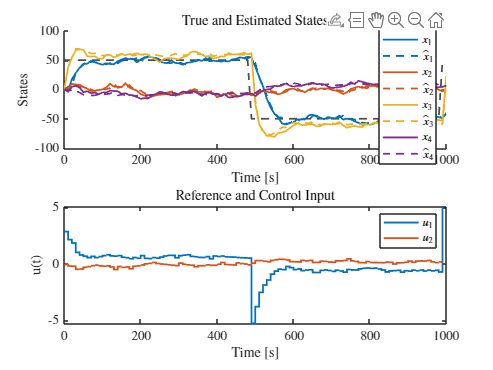

clear
rng(203829)
addpath('functions')
set(groot, 'defaultTextInterpreter', 'latex');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
plotPos = [100 100 800, 400];


%% --- system definition ---
Ts = 10;    % sample time [s]

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];

B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];

C = [1, 0, 0, 0;
     0, 1, 0, 0];

% cost / noise‐covariance matrices (as given)
Q= [8.0209, 0.2260, 1.5334, 0.0812;
       0.2260, 8.0209, 0.0812, 1.5334;
       1.5334, 0.0812, 7.4082, 0.0172;
       0.0812, 1.5334, 0.0172, 7.4082];
R = eye(2);    % = R2

W = Q;         % assumed process‐noise covariance
V = R;         % assumed measurement‐noise covariance

%% --- LQR controller design ---
[K,~,~] = dlqr(A,B,diag([1,1,0,0]),R*250);
% lambda = eig(A)
% K = place(A,B,lambda*0.85)

%% --- Kalman filter design (steady‐state) ---
%   L is the state‐estimator gain:  xhat+ = A*xhat + B*u + L*(y - C*xhat)
% Solve the discrete Riccati equation
[P,~,~] = dare(A', C', Q, R);
[P,~,~] = idare(A', C', Q, R);

% Compute stationary Kalman gain
Kf = P * C' / (C * P * C' + R);


%% --- simulation setup ---
Tfinal = 1000;            % total simulation time [s]
N = Tfinal / Ts;         % number of steps
x     = zeros(4, N+1);   % true state
xhat  = zeros(4, N+1);   % estimated state
y     = zeros(2, N);     % measurements
yhat  = zeros(2, N);     % predicted outputs
u     = zeros(2, N);     % control inputs

rng(0);  % for reproducible noise

T = N; % Periode in sampels
ref1 = 50*square(2*pi*1/T*(1:N),50);
ref2 = zeros(1,N);
ref = [ref1;ref2];
dcG = (C*(eye(4) - (A-B*K))^(-1) * B)^-1;
for k = 1:N
    % Simulate measurement
    v = mvnrnd(zeros(size(R,1),1), R)';
    y(:,k) = C*x(:,k) + v;

    % Controller (if any), could be 0 or feedback
    u(:,k) = -K*xhat(:,k) + dcG * ref(:,k);

    % True system evolution
    w = mvnrnd(zeros(size(Q,1),1), Q)';
    x(:,k+1) = A*x(:,k) + B*u(:,k) + w;

    % Stationary Kalman filter update
    innov = y(:,k) - C*xhat(:,k);
    xhat(:,k+1) = A*xhat(:,k) + B*u(:,k) + Kf*innov;
    yhat(:,k)   = C*xhat(:,k);
end

time = 0:Ts:Tfinal;
colors = lines(4);
%% --- plotting ---
figure;
subplot(2,1,1); hold on
plot(time(1:end-1), ref(1,:), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
for i = 1:4
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend({'$r_1$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'}, ...
       'Location','best');
title('True and Estimated States');

subplot(2,1,2); 
stairs(time(1:end-1), u(:,:)', '-',  'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$');
title('Reference and Control Input');

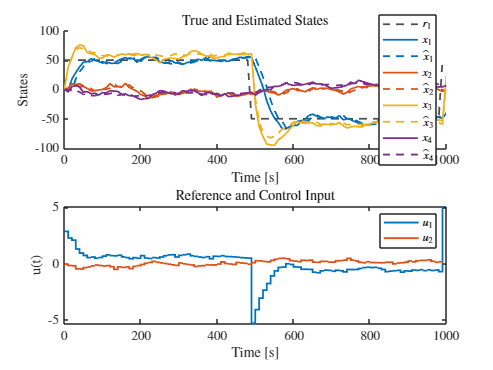

%% --- system definition and LQR design (unchanged) ---
Ts = 10;                          % sample time [s]
A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];
B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];
C = [1, 0, 0, 0;
     0, 1, 0, 0];

Q_c = [8.0209, 0.2260, 1.5334, 0.0812;
       0.2260, 8.0209, 0.0812, 1.5334;
       1.5334, 0.0812, 7.4082, 0.0172;
       0.0812, 1.5334, 0.0172, 7.4082];
R_c = eye(2);

[K,~,~] = dlqr(A,B,diag([1,1,0,0]),R_c*250);
% lambda = eig(A)
% K = place(A,B,lambda*0.85)

%% --- reference and DC-gain computation ---
Tfinal = 1000;                % total sim time [s]
N      = Tfinal / Ts;        % # of steps
T      =  N;                  % choose one period = N steps

% 50%-duty, ±10 square wave in the first output channel:
ref1 = 50 * square(2*pi*(1/T)*(1:N), 50);
ref2 = zeros(1, N);
ref  = [ref1; ref2];         % 2×N reference

% compute DC-gain inverse for perfect steady-state tracking:
dcG = (C*(eye(4) - (A-B*K))^(-1) * B)^-1;

%% --- Kalman and simulation setup ---
W    = Q_c;               % process‐noise cov
V    = R_c;               % measurement‐noise cov
x    = zeros(4, N+1);     % true state
xhat = zeros(4, N+1);     % estimated state
P    = 1*eye(4);        % init error‐covariance
u    = zeros(2, N);
y    = zeros(2, N);
P_hist = zeros(4, N);

rng(0);
for k = 1:N
  %--- measurement ---
  y(:,k) = C*x(:,k) + mvnrnd(zeros(2,1),V)';

  %--- control law w/ feed-forward ---
  u(:,k) = -K*xhat(:,k) + dcG * ref(:,k);

  %--- true‐state update ---
  x(:,k+1) = A*x(:,k) + B*u(:,k) + mvnrnd(zeros(4,1),W)';

  %--- Kalman predict ---
  xhat_pred = A*xhat(:,k) + B*u(:,k);
  P_pred    = A*P*A' + W;

  %--- Kalman update ---
  S      = C*P_pred*C' + V;
  Kf     = P_pred*C'/S;

  innov  = y(:,k) - C*xhat_pred;
  xhat(:,k+1) = xhat_pred + Kf*innov;
  P      = (eye(4) - Kf*C)*P_pred;
  P_hist(:,k) = diag(P);
end

%% --- plotting ---
time = 0:Ts:Tfinal;
colors = lines(4);  % get a color for each state

figure;
subplot(2,1,1); hold on
plot(time(1:end-1), ref(1,:), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
for i = 1:4
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend({'$r_1$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'}, ...
       'Location','best');
title('True and Estimated States');

subplot(2,1,2); 
stairs(time(1:end-1), u(:,:)', '-',  'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$');
title('Reference and Control Input');

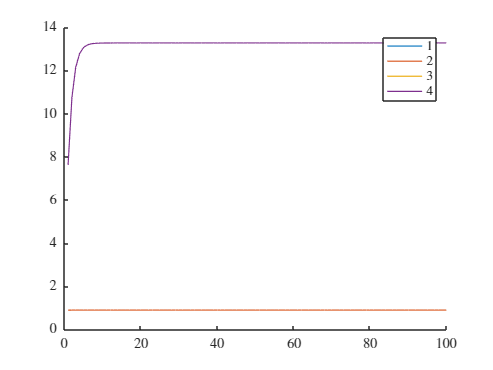


figure; hold on
plot(P_hist(1,:));
plot(P_hist(2,:));
plot(P_hist(3,:));
plot(P_hist(4,:));
legend("1","2","3","4")
hold off

%% ------------------------------------------------------------------------
%  GPC with Stationary Kalman State Estimation for Discrete‐Time LTI System
%% ------------------------------------------------------------------------
clear; clc;

%% 1) System definition
Ts     = 10;               % sample time [s]
Tfinal = 1000;             % total simulation time [s]
Nsim   = Tfinal / Ts;      % number of steps

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];
B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];
C = [1, 0, 0, 0;
     0, 1, 0, 0];

[nx, nu] = size(B);
ny        = size(C,1);

%% 2) Kalman filter design (steady‐state gain)
Qk_f = [8.0209, 0.2260, 1.5334, 0.0812;
         0.2260, 8.0209, 0.0812, 1.5334;
         1.5334, 0.0812, 7.4082, 0.0172;
         0.0812, 1.5334, 0.0172, 7.4082];  % process‐noise cov
Rk_f = eye(ny);                           % meas‐noise cov
[ Lk, ~, ~ ] = dlqe(A, eye(nx), C, Qk_f, Rk_f);  
% Lk: stationary Kalman gain

%% 3) GPC tuning parameters
Np  = 10;                                      % prediction horizon
Qy  = kron(eye(Np), eye(ny));                  % output‐tracking weight
Ru  = 0.01 * eye(nu*Np);                       % input move weight

%% 4) Build prediction matrices
Theta   = zeros(ny*Np, nx);
Gamma_y = zeros(ny*Np, nu*Np);
for i = 1:Np
    Theta((i-1)*ny+1:i*ny, :) = C * (A^i);
    for j = 1:i
        idx_row = (i-1)*ny+1 : i*ny;
        idx_col = (j-1)*nu+1 : j*nu;
        Gamma_y(idx_row, idx_col) = C * (A^(i-j)) * B;
    end
end

% Precompute Hessian for QP
H = Gamma_y' * Qy * Gamma_y + Ru;
opts = optimoptions('quadprog','Display','off');

%% 5) Reference signal (±10 square wave on output 1)
ref1 = 50 * square(2*pi*(2/(Nsim+ Np))*(1:Nsim + Np), 50);
ref2 = zeros(1, Nsim + Np);
ref  = [ref1; ref2];       % size 2×Nsim

%% 6) Preallocate
x     = zeros(nx,   Nsim+1);   % true state
xhat  = zeros(nx,   Nsim+1);   % estimated state
u     = zeros(nu,   Nsim);
y     = zeros(ny,   Nsim);
P    = 1*eye(4);        % init error‐covariance
P_pred    = P;
xhat_pred = xhat(:,1);
Xpred   = zeros(nx, Np+1, Nsim);  % store Np‐step predictions
rng(0);  % for reproducibility

%% 7) Main simulation loop
u_prev = zeros(nu,1);
for k = 1:Nsim
    %--- simulate measurement y(k) with noise
    y(:,k) = C*x(:,k) + mvnrnd(zeros(ny,1), Rk_f)';
    
    %--- Kalman update ---
    S      = C*P_pred*C' + Rk_f;
    Lf     = P_pred*C'/S;
    
    %--- Kalman correct
    innov      = y(:,k) - C*xhat_pred;
    xhat(:,k)  = xhat_pred + Lk * innov;
    
    
    P = (eye(4) - Lf*C)*P_pred;
    P_hist(:,k) = diag(P);
    
    
    %--- GPC: form QP linear term
    r_win = reshape(ref(:, k:k+Np-1), [], 1);% stacked reference
    f = Gamma_y' * Qy * (Theta * xhat(:, k) - r_win);
    
    %--- solve for future moves U = [du0; du1; ... ; du_{Np-1}]
    % U = quadprog(H, f, [], [], [], [], [], [], [], opts);
    
    %--- apply control law
    % U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Theta * xhat(:, k) - r_win);
    U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Theta * xhat(:, k) - r_win);
    
    %--- apply only first move
    % u(:, k) = U_N(1:nu);
    u(:, k) = [eye(nu), zeros(nu,nu*Np - nu)] * U_N;
    
    u_prev = u(:, k);
    
    % Compute Np‐step ahead state predictions
    Xpred(:,1,k) = xhat(:,k);
    for j = 1:Np
    Uj = U_N((j-1)*nu+1:j*nu);
    Xpred(:,j+1,k) = A*Xpred(:,j,k) + B*Uj;
    end
    
    
    %--- simulate true system with process noise
    x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx, 1), Qk_f)';
    
    
    
    %--- Kalman predict
    xhat_pred = A*xhat(:,k) + B*u_prev;
    P_pred    = A*P*A' + Qk_f;

end

%% 8) Plotting
time   = 0:Ts:Tfinal;
colors = lines(4);

figure;
subplot(2,1,1); hold on
plot(time(1:end-1), ref(1,1:Nsim), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
for i = 1:2
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend({'$r_1$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'}, ...
       'Interpreter','latex','Location','best');

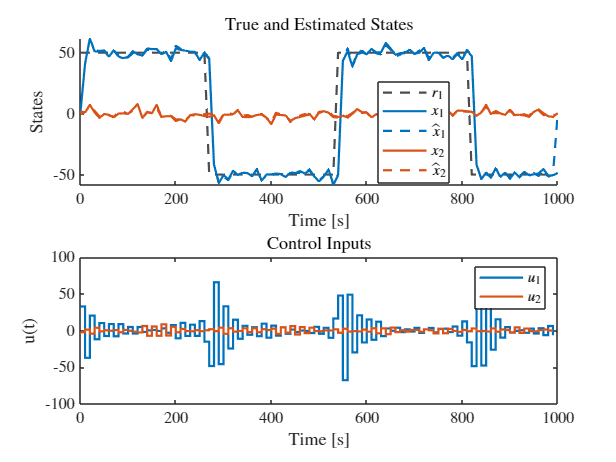

title('True and Estimated States','Interpreter','latex');

subplot(2,1,2);
stairs(time(1:end-1), u', '-', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$','Interpreter','latex');
title('Control Inputs','Interpreter','latex');

%% 8) (Optional) Plot predictions at a specific k
k_plot = 100;  % choose a time instant
t_pred = (k_plot*Ts) + (0:Np)*Ts;
d=-0;
figure; hold on;
for i = 1:nx-2
    plot((0:Nsim)*Ts, x(i,:), '-', 'LineWidth',1.5);
    plot((0:Nsim)*Ts,xhat(i,:), '-', 'LineWidth',1.5);
    % plot(t_pred, squeeze(Xpred(i,:,k_plot)), '--', 'LineWidth',1.5);
    plot((Np+d:Nsim-1+d)*Ts, squeeze(Xpred(i,Np+d+1,1:Nsim-Np))', '--', 'LineWidth',1.5);
end
hold off
xlabel('Time [s]');
ylabel('States and Predictions');
legend( ...
  [strcat("x",string(1:nx)); ...
  strcat("xhat", string(1:nx)); ...
  strcat("pred x",    string(1:nx))], ...
  'Location','best');

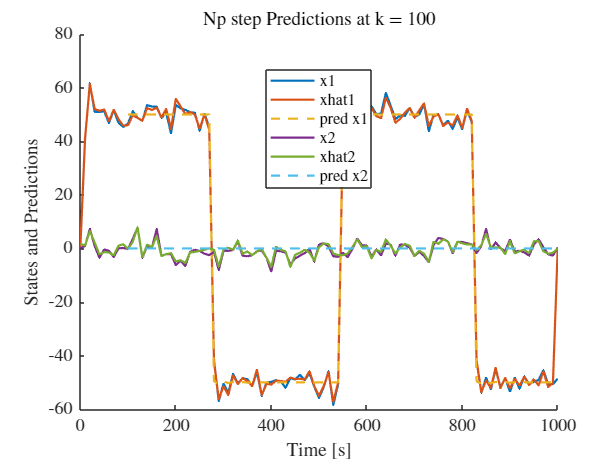

title(sprintf('Np step Predictions at k = %d', k_plot));


% figure; hold on
% plot(P_hist(1,:));
% plot(P_hist(2,:),'--');
% plot(P_hist(3,:));
% plot(P_hist(4,:),'--');
% legend("1","2","3","4")
% hold off







%% ------------------------------------------------------------------------
%  GPC with Stationary Kalman State Estimation for Discrete‐Time LTI System
%% ------------------------------------------------------------------------
clear; clc;

%% 1) System definition
Ts     = 10;               % sample time [s]
Tfinal = 1000;             % total simulation time [s]
Nsim   = Tfinal / Ts;      % number of steps

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];
B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];
C = [1, 0, 0, 0;
     0, 1, 0, 0];



[nx, nu] = size(B);
ny        = size(C,1);

%% 2) Kalman filter design (steady‐state gain)
Qk_f = [8.0209, 0.2260, 1.5334, 0.0812;
         0.2260, 8.0209, 0.0812, 1.5334;
         1.5334, 0.0812, 7.4082, 0.0172;
         0.0812, 1.5334, 0.0172, 7.4082];  % process‐noise cov
Rk_f = eye(ny);                           % meas‐noise cov


kappa = [0.99999,0.99999,0.99999,0.99999];
sigma_d = [0.01,0.01,0.01,0.01];
A_aug = [A,eye(4);zeros(4,4),diag(kappa)]

A_aug =     0.7901    0.0238    0.1667    0.0081    1.0000         0         0         0
    0.0238    0.7901    0.0081    0.1667         0    1.0000         0         0
    0.1667    0.0081    0.7236    0.0014         0         0    1.0000         0
    0.0081    0.1667    0.0014    0.7236         0         0         0    1.0000
         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0    1.0000


B_aug = [B;zeros(4,2)]

B_aug =     1.4459    0.0622
    0.0622    1.4459
   13.3615    0.0077
    0.0077   13.3615
         0         0
         0         0
         0         0
         0         0


C_aug =  [C, zeros(2,4)]

C_aug =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0


Qk_f_aug = [Qk_f,zeros(4,4);zeros(4,4),diag(sigma_d.^2)]

Qk_f_aug =     8.0209    0.2260    1.5334    0.0812         0         0         0         0
    0.2260    8.0209    0.0812    1.5334         0         0         0         0
    1.5334    0.0812    7.4082    0.0172         0         0         0         0
    0.0812    1.5334    0.0172    7.4082         0         0         0         0
         0         0         0         0    0.0001         0         0         0
         0         0         0         0         0    0.0001         0         0
         0         0         0         0         0         0    0.0001         0
         0         0         0         0         0         0         0    0.0001




% A = A_aug;
% B = B_aug;
% C = C_aug;

[nx, nu] = size(B_aug);
ny        = size(C_aug,1);


% Qk_f = Qk_f_aug;





[ Lk, ~, ~ ] = dlqe(A_aug, eye(nx), C_aug, Qk_f_aug, Rk_f);  
% Lk: stationary Kalman gain

%% 3) GPC tuning parameters
Np  = 10;                                      % prediction horizon
Qy  = kron(eye(Np), eye(ny));                  % output‐tracking weight
Ru  = 0.01 * eye(nu*Np);                       % input move weight

%% 4) Build prediction matrices
Theta   = zeros(ny*Np, nx);
Gamma_y = zeros(ny*Np, nu*Np);
for i = 1:Np
    Theta((i-1)*ny+1:i*ny, :) = C_aug * (A_aug^i);
    for j = 1:i
        idx_row = (i-1)*ny+1 : i*ny;
        idx_col = (j-1)*nu+1 : j*nu;
        Gamma_y(idx_row, idx_col) = C_aug * (A_aug^(i-j)) * B_aug;
    end
end

% Precompute Hessian for QP
H = Gamma_y' * Qy * Gamma_y + Ru;
opts = optimoptions('quadprog','Display','off');

%% 5) Reference signal (±10 square wave on output 1)
ref1 = 50 * square(2*pi*(2/(Nsim+ Np))*(1:Nsim + Np), 50);
ref2 = zeros(1, Nsim + Np);
ref  = [ref1; ref2];       % size 2×Nsim

%% 6) Preallocate
x     = zeros(nx/2,   Nsim+1);   % true state
xhat  = zeros(nx,   Nsim+1);   % estimated state
d  = [1*ones(1,   Nsim+1);
    -0*ones(1,   Nsim+1);
    -0*ones(1,   Nsim+1);
    0*ones(1,   Nsim+1)];   % estimated state

u     = zeros(nu,   Nsim);
y     = zeros(ny,   Nsim);
P    = diag([1,1,1,1,10,10,10,10]);        % init error‐covariance
P_pred    = P;
xhat_pred = xhat(:,1);
Xpred   = zeros(nx, Np+1, Nsim);  % store Np‐step predictions
rng(0);  % for reproducibility

%% 7) Main simulation loop
u_prev = zeros(nu,1);
for k = 1:Nsim
    %--- simulate measurement y(k) with noise
    y(:,k) = C*x(:,k) + mvnrnd(zeros(ny,1), Rk_f)';
    
    %--- Kalman update ---
    S      = C_aug*P_pred*C_aug' + Rk_f;
    Lf     = P_pred*C_aug'/S;
    
    %--- Kalman correct
    innov      = y(:,k) - C_aug*xhat_pred;
    xhat(:,k)  = xhat_pred + Lf * innov;
    
    
    P = (eye(size(P,1)) - Lf*C_aug)*P_pred;
    P_hist(:,k) = diag(P);
    
    
    %--- GPC: form QP linear term
    r_win = reshape(ref(:, k:k+Np-1), [], 1);% stacked reference
    f = Gamma_y' * Qy * (Theta * xhat(:, k) - r_win);
    
    %--- solve for future moves U = [du0; du1; ... ; du_{Np-1}]
    % U = quadprog(H, f, [], [], [], [], [], [], [], opts);
    
    %--- apply control law
    % U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Theta * xhat(:, k) - r_win);
    U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Theta * xhat(:, k) - r_win);
    
    %--- apply only first move
    % u(:, k) = U_N(1:nu);
    u(:, k) = [eye(nu), zeros(nu,nu*Np - nu)] * U_N;
    
    u_prev = u(:, k);
    
    % Compute Np‐step ahead state predictions
    Xpred(:,1,k) = xhat(:,k);
    for j = 1:Np
    Uj = U_N((j-1)*nu+1:j*nu);
    Xpred(:,j+1,k) = A_aug*Xpred(:,j,k) + B_aug*Uj;
    end
    
    
    %--- simulate true system with process noise
    x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx/2, 1), Qk_f)' + d(:,k);
    
    
    
    %--- Kalman predict
    xhat_pred = A_aug*xhat(:,k) + B_aug*u_prev;
    P_pred    = A_aug*P*A_aug' + Qk_f_aug;

end

%% 8) Plotting
time   = 0:Ts:Tfinal;
colors = lines(4);

figure;
subplot(2,1,1); hold on
plot(time(1:end-1), ref(1,1:Nsim), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
for i = 1:2
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend({'$r_1$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'}, ...
       'Interpreter','latex','Location','best');

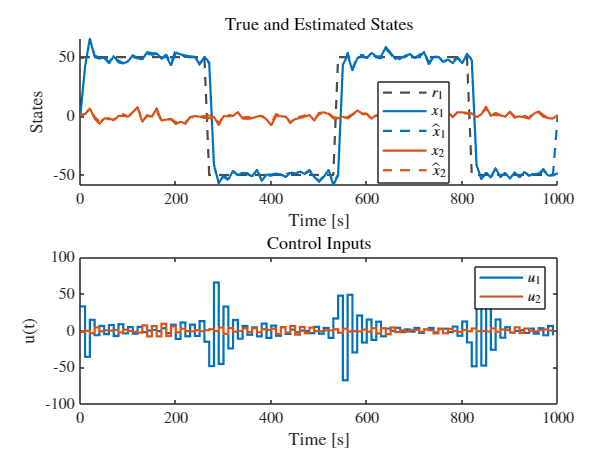

title('True and Estimated States','Interpreter','latex');

subplot(2,1,2);
stairs(time(1:end-1), u', '-', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$','Interpreter','latex');
title('Control Inputs','Interpreter','latex');

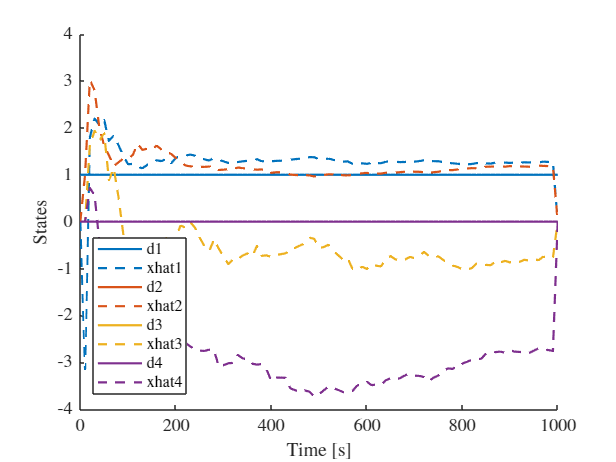

figure(); hold on
for i = 5:8
    plot(time,  d(i-4,:),     '-',  'Color', colors(i-4,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i-4,:), 'LineWidth', 1.5);
end
hold off
xlabel('Time [s]');
ylabel('States');
legend([strcat("d",string(1:nx/2));strcat("xhat",string(1:nx/2))], ...
       'Interpreter','latex','Location','best');



%% 8) (Optional) Plot predictions at a specific k
k_plot = 100;  % choose a time instant
t_pred = (k_plot*Ts) + (0:Np)*Ts;

figure; hold on;
for i = 1:nx-6
    plot((0:Nsim)*Ts, x(i,:), '-', 'LineWidth',1.5);
    plot((0:Nsim)*Ts,xhat(i,:), '-', 'LineWidth',1.5);
    % plot(t_pred, squeeze(Xpred(i,:,k_plot)), '--', 'LineWidth',1.5);
    plot((Np:Nsim-1)*Ts, squeeze(Xpred(i,Np+1,1:Nsim-Np))', '--', 'LineWidth',1.5);
end
hold off
xlabel('Time [s]');
ylabel('States and Predictions');
legend( ...
  [strcat("x",string(1:nx)); ...
  strcat("xhat", string(1:nx)); ...
  strcat("pred x",    string(1:nx))], ...
  'Location','best');

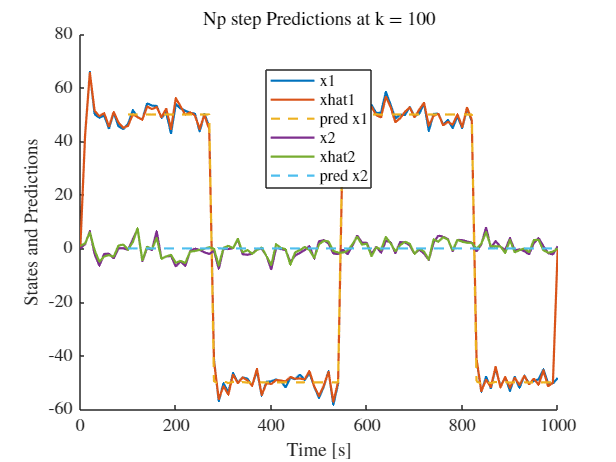

title(sprintf('Np step Predictions at k = %d', k_plot));

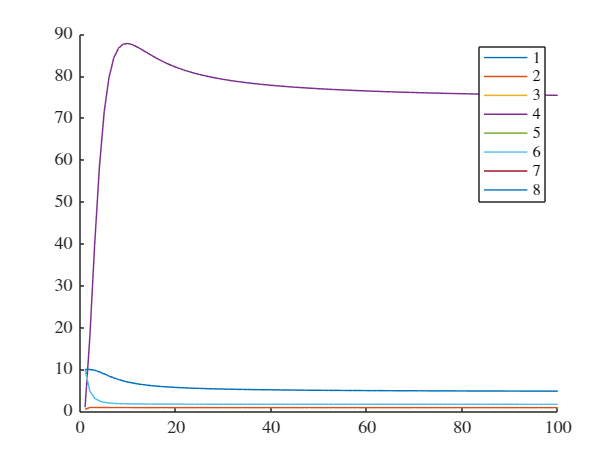


figure; hold on
for i = 1:nx
    plot(P_hist(i,:));
end
legend(strcat("",string(1:nx)))
hold off


%% ------------------------------------------------------------------------
%  GPC with Stationary Kalman State Estimation for Discrete‐Time LTI System
%% ------------------------------------------------------------------------
clear; clc;

%% 1) System definition
Ts     = 10;               % sample time [s]
Tfinal = 1000;             % total simulation time [s]
Nsim   = Tfinal / Ts;      % number of steps

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];
B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];
C = [1, 0, 0, 0;
     0, 1, 0, 0];



[nx, nu] = size(B);
ny        = size(C,1);

%% 2) Kalman filter design (steady‐state gain)
Qk_f = [8.0209, 0.2260, 1.5334, 0.0812;
         0.2260, 8.0209, 0.0812, 1.5334;
         1.5334, 0.0812, 7.4082, 0.0172;
         0.0812, 1.5334, 0.0172, 7.4082];  % process‐noise cov
Rk_f = eye(ny);                           % meas‐noise cov


kappa = 0.9999;
sigma_d = 5;
d_in = [0,1,0,1]';

A_aug = [A,d_in;zeros(1,4),diag(kappa)]

A_aug =     0.7901    0.0238    0.1667    0.0081         0
    0.0238    0.7901    0.0081    0.1667    1.0000
    0.1667    0.0081    0.7236    0.0014         0
    0.0081    0.1667    0.0014    0.7236    1.0000
         0         0         0         0    0.9999


B_aug = [B;zeros(1,2)]

B_aug =     1.4459    0.0622
    0.0622    1.4459
   13.3615    0.0077
    0.0077   13.3615
         0         0


C_aug =  [C, zeros(2,1)]

C_aug =      1     0     0     0     0
     0     1     0     0     0


Qk_f_aug = [Qk_f,zeros(4,1);zeros(1,4),diag(sigma_d.^2)]

Qk_f_aug =     8.0209    0.2260    1.5334    0.0812         0
    0.2260    8.0209    0.0812    1.5334         0
    1.5334    0.0812    7.4082    0.0172         0
    0.0812    1.5334    0.0172    7.4082         0
         0         0         0         0   25.0000




% A = A_aug;
% B = B_aug;
% C = C_aug;

[nx, nu] = size(B_aug);
ny        = size(C_aug,1);


% Qk_f = Qk_f_aug;





[ Lk, ~, ~ ] = dlqe(A_aug, eye(nx), C_aug, Qk_f_aug, Rk_f);  
% Lk: stationary Kalman gain

%% 3) GPC tuning parameters
Np  = 10;                                      % prediction horizon
Qy  = kron(eye(Np), eye(ny));                  % output‐tracking weight
Ru  = 0.01 * eye(nu*Np);                       % input move weight

%% 4) Build prediction matrices
Theta   = zeros(ny*Np, nx);
Gamma_y = zeros(ny*Np, nu*Np);
for i = 1:Np
    Theta((i-1)*ny+1:i*ny, :) = C_aug * (A_aug^i);
    for j = 1:i
        idx_row = (i-1)*ny+1 : i*ny;
        idx_col = (j-1)*nu+1 : j*nu;
        Gamma_y(idx_row, idx_col) = C_aug * (A_aug^(i-j)) * B_aug;
    end
end

% Precompute Hessian for QP
H = Gamma_y' * Qy * Gamma_y + Ru;
opts = optimoptions('quadprog','Display','off');

%% 5) Reference signal (±10 square wave on output 1)
ref1 = 50 * square(2*pi*(2/(Nsim+ Np))*(1:Nsim + Np), 50);
ref2 = zeros(1, Nsim + Np);
ref  = [ref1; ref2];       % size 2×Nsim

%% 6) Preallocate
x     = zeros(nx-length(sigma_d),   Nsim+1);   % true state
xhat  = zeros(nx,   Nsim+1);   % estimated state
% d  = 5*ones(1,   Nsim+1);
d = -10*square(2*pi*(2/(Nsim+ 1))*(1:Nsim + 1), 50);

u     = zeros(nu,   Nsim);
y     = zeros(ny,   Nsim);
P    = 5*eye(nx);        % init error‐covariance
P_pred    = P;
xhat_pred = xhat(:,1);
Xpred   = zeros(nx, Np+1, Nsim);  % store Np‐step predictions
rng(0);  % for reproducibility

%% 7) Main simulation loop
u_prev = zeros(nu,1);
for k = 1:Nsim
    %--- simulate measurement y(k) with noise
    y(:,k) = C*x(:,k) + mvnrnd(zeros(ny,1), Rk_f)';
    
    %--- Kalman update ---
    S      = C_aug*P_pred*C_aug' + Rk_f;
    Lf     = P_pred*C_aug'/S;
    
    %--- Kalman correct
    innov      = y(:,k) - C_aug*xhat_pred;
    xhat(:,k)  = xhat_pred + Lf * innov;
    
    
    P = (eye(size(P,1)) - Lf*C_aug)*P_pred;
    P_hist(:,k) = diag(P);
    
    
    %--- GPC: form QP linear term
    r_win = reshape(ref(:, k:k+Np-1), [], 1);% stacked reference
    f = Gamma_y' * Qy * (Theta * xhat(:, k) - r_win);
    
    %--- solve for future moves U = [du0; du1; ... ; du_{Np-1}]
    % U = quadprog(H, f, [], [], [], [], [], [], [], opts);
    
    %--- apply control law
    % U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Theta * xhat(:, k) - r_win);
    U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Theta * xhat(:, k) - r_win);
    
    %--- apply only first move
    % u(:, k) = U_N(1:nu);
    u(:, k) = [eye(nu), zeros(nu,nu*Np - nu)] * U_N;
    % u(:,k) = [1;-1];
    u_prev = u(:, k);
    
    % Compute Np‐step ahead state predictions
    Xpred(:,1,k) = xhat(:,k);
    for j = 1:Np
    Uj = U_N((j-1)*nu+1:j*nu);
    Xpred(:,j+1,k) = A_aug*Xpred(:,j,k) + B_aug*Uj;
    end
    
    
    %--- simulate true system with process noise
    x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx - length(sigma_d), 1), Qk_f)' + d_in*d(:,k);
    
    
    
    %--- Kalman predict
    xhat_pred = A_aug*xhat(:,k) + B_aug*u_prev;
    P_pred    = A_aug*P*A_aug' + Qk_f_aug;

end

%% 8) Plotting
time   = 0:Ts:Tfinal;
colors = lines(4);

figure;
subplot(2,1,1); hold on
plot(time(1:end-1), ref(1,1:Nsim), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
for i = 1:2
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend({'$r_1$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'}, ...
       'Interpreter','latex','Location','best');

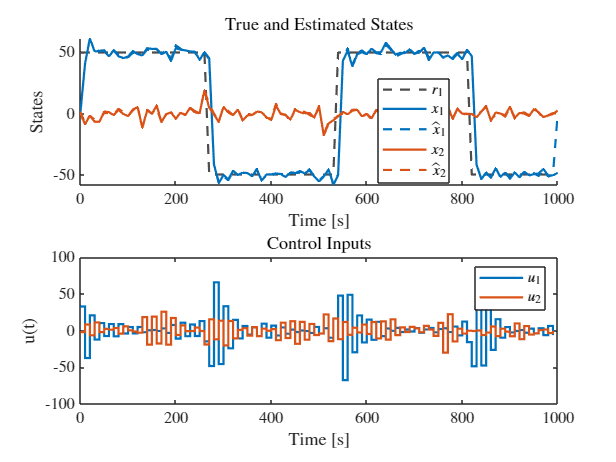

title('True and Estimated States','Interpreter','latex');

subplot(2,1,2);
stairs(time(1:end-1), u', '-', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$','Interpreter','latex');
title('Control Inputs','Interpreter','latex');

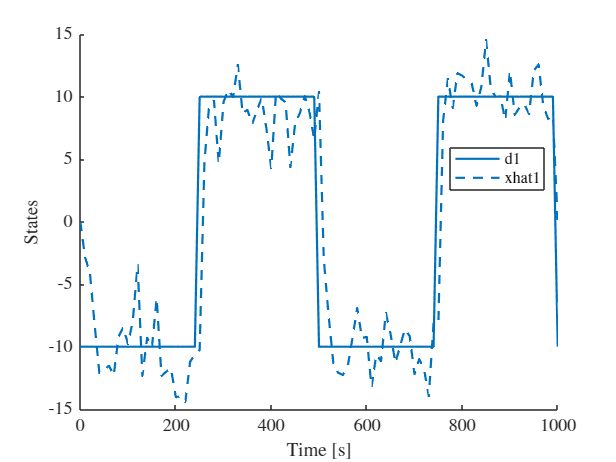

figure(); hold on

plot(time,  d(1,:),     '-',  'Color', colors(1,:), 'LineWidth', 1.5);
plot(time, xhat(5,:), '--', 'Color', colors(1,:), 'LineWidth', 1.5);

hold off
xlabel('Time [s]');
ylabel('States');
legend([strcat("d",string(1:nx/2));strcat("xhat",string(1:nx/2))], ...
       'Interpreter','latex','Location','best');

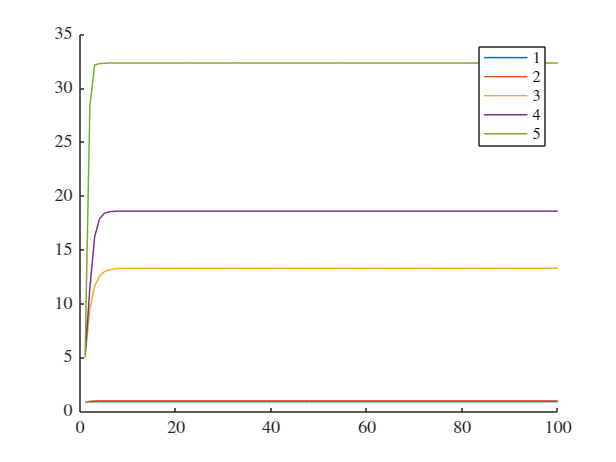



figure; hold on
for i = 1:nx
    plot(P_hist(i,:));
end
legend(strcat("",string(1:nx)))
hold off

%% ------------------------------------------------------------------------
%  GPC with Stationary Kalman State Estimation for Discrete‐Time LTI System
%% ------------------------------------------------------------------------
clear; clc;

%% 1) System definition
Ts     = 10;               % sample time [s]
Tfinal = 1000;             % total simulation time [s]
Nsim   = Tfinal / Ts;      % number of steps

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];
B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];
C = [1, 0, 0, 0;
     0, 1, 0, 0];

[nx, nu] = size(B);
ny        = size(C,1);

%% 2) Kalman filter design (steady‐state gain)
Qk_f = [8.0209, 0.2260, 1.5334, 0.0812;
         0.2260, 8.0209, 0.0812, 1.5334;
         1.5334, 0.0812, 7.4082, 0.0172;
         0.0812, 1.5334, 0.0172, 7.4082];  % process‐noise cov
Rk_f = eye(ny);                           % meas‐noise cov
[ Lk, ~, ~ ] = dlqe(A, eye(nx), C, Qk_f, Rk_f);  
% Lk: stationary Kalman gain

d_in = [0,1,0,1]';
d = -10*square(2*pi*(2/(Nsim+ 1))*(1:Nsim + 1), 50);

%% 3) GPC tuning parameters
Np  = 10;                                      % prediction horizon
Qy  = kron(eye(Np), eye(ny));                  % output‐tracking weight
Ru  = 0.01 * eye(nu*Np);                       % input move weight

%% 4) Build prediction matrices
Theta   = zeros(ny*Np, nx);
Gamma_y = zeros(ny*Np, nu*Np);
for i = 1:Np
    Theta((i-1)*ny+1:i*ny, :) = C * (A^i);
    for j = 1:i
        idx_row = (i-1)*ny+1 : i*ny;
        idx_col = (j-1)*nu+1 : j*nu;
        Gamma_y(idx_row, idx_col) = C * (A^(i-j)) * B;
    end
end

% Precompute Hessian for QP
H = Gamma_y' * Qy * Gamma_y + Ru;
opts = optimoptions('quadprog','Display','off');

%% 5) Reference signal (±10 square wave on output 1)
ref1 = 50 * square(2*pi*(2/(Nsim+ Np))*(1:Nsim + Np), 50);
ref2 = zeros(1, Nsim + Np);
ref  = [ref1; ref2];       % size 2×Nsim

%% 6) Preallocate
x     = zeros(nx,   Nsim+1);   % true state
xhat  = zeros(nx,   Nsim+1);   % estimated state
u     = zeros(nu,   Nsim);
y     = zeros(ny,   Nsim);
P    = 1*eye(4);        % init error‐covariance
P_pred    = P;
xhat_pred = xhat(:,1);
Xpred   = zeros(nx, Np+1, Nsim);  % store Np‐step predictions
rng(0);  % for reproducibility

%% 7) Main simulation loop
u_prev = zeros(nu,1);
for k = 1:Nsim
    %--- simulate measurement y(k) with noise
    y(:,k) = C*x(:,k) + mvnrnd(zeros(ny,1), Rk_f)';
    
    %--- Kalman update ---
    S      = C*P_pred*C' + Rk_f;
    Lf     = P_pred*C'/S;
    
    %--- Kalman correct
    innov      = y(:,k) - C*xhat_pred;
    xhat(:,k)  = xhat_pred + Lk * innov;
    
    
    P = (eye(4) - Lf*C)*P_pred;
    P_hist(:,k) = diag(P);
    
    
    %--- GPC: form QP linear term
    r_win = reshape(ref(:, k:k+Np-1), [], 1);% stacked reference
    f = Gamma_y' * Qy * (Theta * xhat(:, k) - r_win);
    
    %--- solve for future moves U = [du0; du1; ... ; du_{Np-1}]
    % U = quadprog(H, f, [], [], [], [], [], [], [], opts);
    
    %--- apply control law
    % U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Theta * xhat(:, k) - r_win);
    U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Theta * xhat(:, k) - r_win);
    
    %--- apply only first move
    % u(:, k) = U_N(1:nu);
    u(:, k) = [eye(nu), zeros(nu,nu*Np - nu)] * U_N;
    
    u_prev = u(:, k);
    
    % Compute Np‐step ahead state predictions
    Xpred(:,1,k) = xhat(:,k);
    for j = 1:Np
    Uj = U_N((j-1)*nu+1:j*nu);
    Xpred(:,j+1,k) = A*Xpred(:,j,k) + B*Uj;
    end
    
    
    %--- simulate true system with process noise(
    x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx, 1), Qk_f)' + d_in * d(k);
    
    
    
    %--- Kalman predict
    xhat_pred = A*xhat(:,k) + B*u_prev;
    P_pred    = A*P*A' + Qk_f;

end

%% 8) Plotting
time   = 0:Ts:Tfinal;
colors = lines(4);

figure;
subplot(2,1,1); hold on
plot(time(1:end-1), ref(1,1:Nsim), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
for i = 1:2
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend({'$r_1$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'}, ...
       'Interpreter','latex','Location','best');

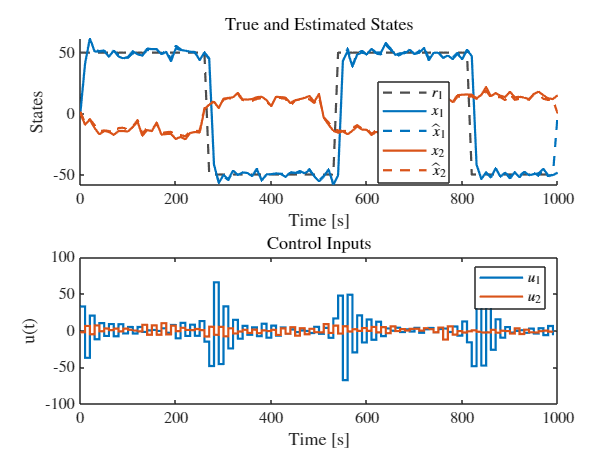

title('True and Estimated States','Interpreter','latex');

subplot(2,1,2);
stairs(time(1:end-1), u', '-', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$','Interpreter','latex');
title('Control Inputs','Interpreter','latex');

%% 8) (Optional) Plot predictions at a specific k
k_plot = 100;  % choose a time instant
t_pred = (k_plot*Ts) + (0:Np)*Ts;
d=-0;
figure; hold on;
for i = 1:nx-2
    plot((0:Nsim)*Ts, x(i,:), '-', 'LineWidth',1.5);
    plot((0:Nsim)*Ts,xhat(i,:), '-', 'LineWidth',1.5);
    % plot(t_pred, squeeze(Xpred(i,:,k_plot)), '--', 'LineWidth',1.5);
    plot((Np+d:Nsim-1+d)*Ts, squeeze(Xpred(i,Np+d+1,1:Nsim-Np))', '--', 'LineWidth',1.5);
end
hold off
xlabel('Time [s]');
ylabel('States and Predictions');
legend( ...
  [strcat("x",string(1:nx)); ...
  strcat("xhat", string(1:nx)); ...
  strcat("pred x",    string(1:nx))], ...
  'Location','best');

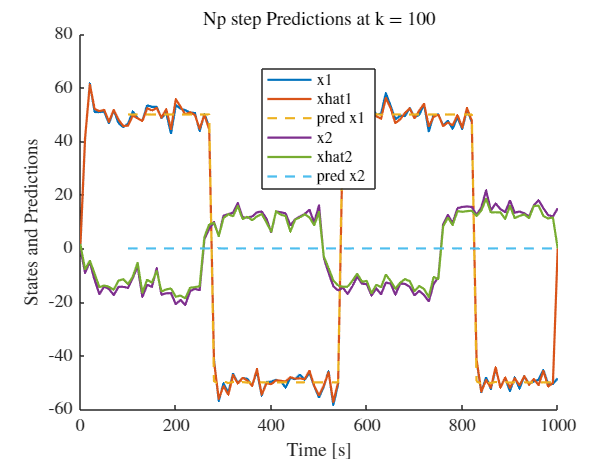

title(sprintf('Np step Predictions at k = %d', k_plot));


% figure; hold on
% plot(P_hist(1,:));
% plot(P_hist(2,:),'--');
% plot(P_hist(3,:));
% plot(P_hist(4,:),'--');
% legend("1","2","3","4")
% hold off

